project_start;

%[scenario,scenarioName,sensors]=loadMCity();
[allData, scenario, sensors,scenarioName]=choose_scenario() ;
assignin('base','Ts', 0.05); 
stopTime=allData(end).Time;
assignin('base','StopTime',stopTime); 
%drivingScenarioDesigner(scenario,sensors)

M=imread(scenarioName,'png');
M1=rgb2gray(M);
[numRow,numCol]=size(M1);
M2=im2double(M1);  
for i=1:numRow
    for j=1:numCol
       if M2(i,j)==1
           M2(i,j)=0;
       elseif M2(i,j)~=1
           M2(i,j)=1;
       end
    end
end
costmap=vehicleCostmap(M2)

costmap =   vehicleCostmap with properties:

        FreeThreshold: 0.2000
    OccupiedThreshold: 0.6500
     CollisionChecker: [1×1 driving.costmap.InflationCollisionChecker]
             CellSize: 1
              MapSize: [1512 1152]
            MapExtent: [0 1152 0 1512]


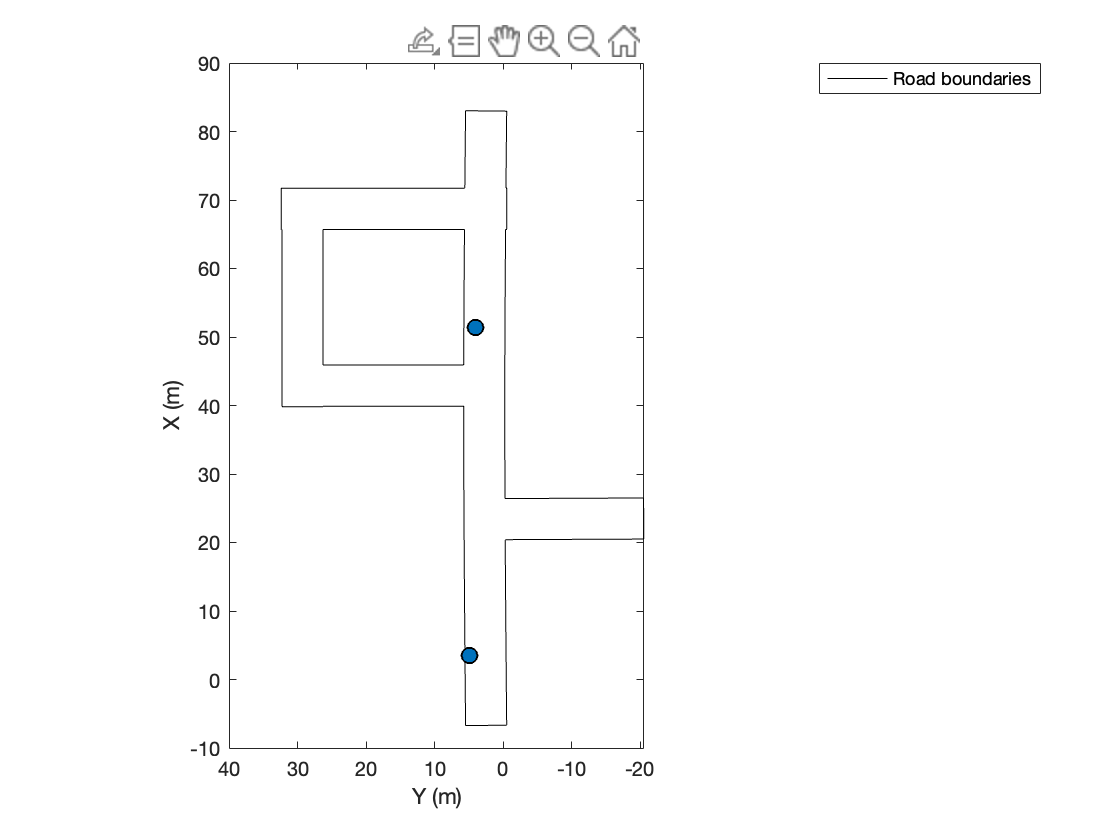


Prompt={'Enter the number of waypoints you want to specify'};
num_of_wpts = str2double(inputdlg(Prompt,'Waypoint density'));
[planner_wpts,ptLabels] = get_start_and_end_pts(scenario,num_of_wpts);

%startPose=[planner_wpts(1,1), planner_wpts(1,2), 0];
%goalPose=[planner_wpts(2,1), planner_wpts(2,2), 0];

%planner = pathPlannerRRT(costmap);
%refPath = plan(planner,startPose,goalPose);
%plot(planner)

[TL_ID,stopSign_ID]=findActorID(scenario);
%restart(scenario);

load('BusActorState');
assignin('base','BusActorState', BusActorState);
load('BusINSMeas');
assignin('base','BusINSMeas', BusINSMeas);

scenarioLocation=append(fullfile(homedir,'scenarios',scenarioName),'.mat');
session=load(scenarioLocation);

EgoWayPts = session.data.ActorSpecifications(1,1).Waypoints; % all other actor waypoints can be gotten the same way
xRef = EgoWayPts(:,1);
yRef = EgoWayPts(:,2);
X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y directiond

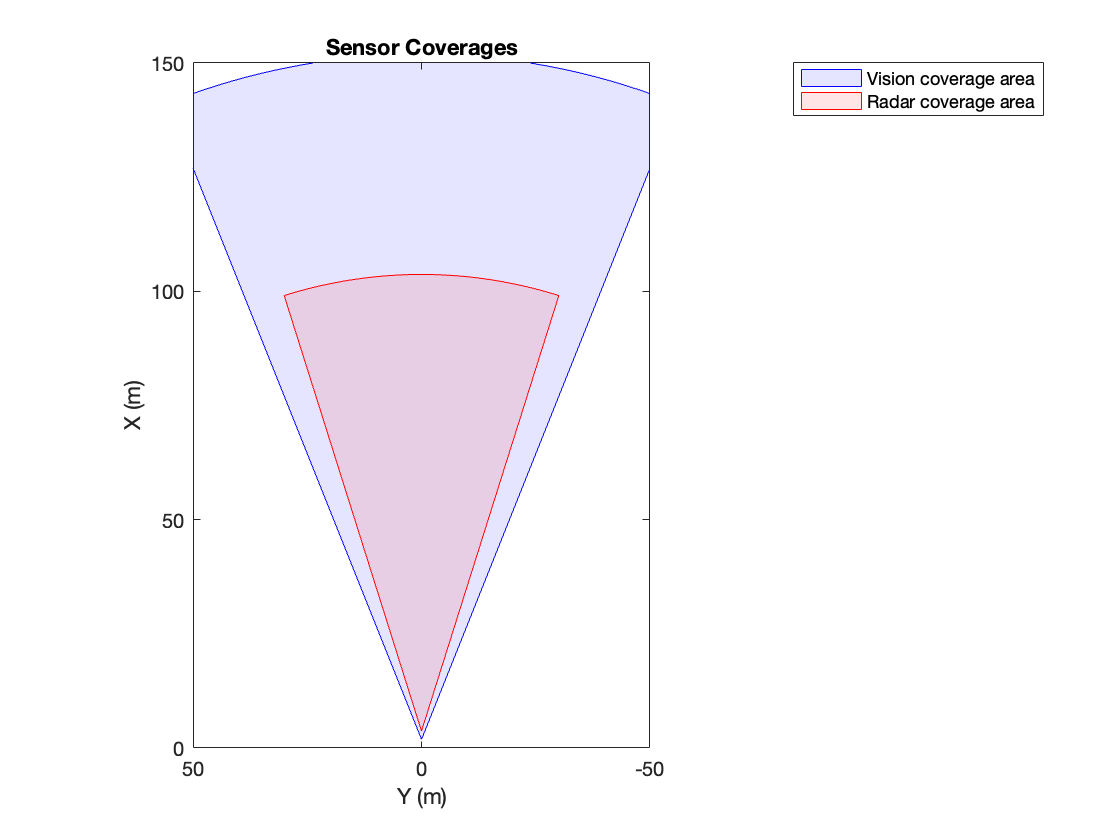

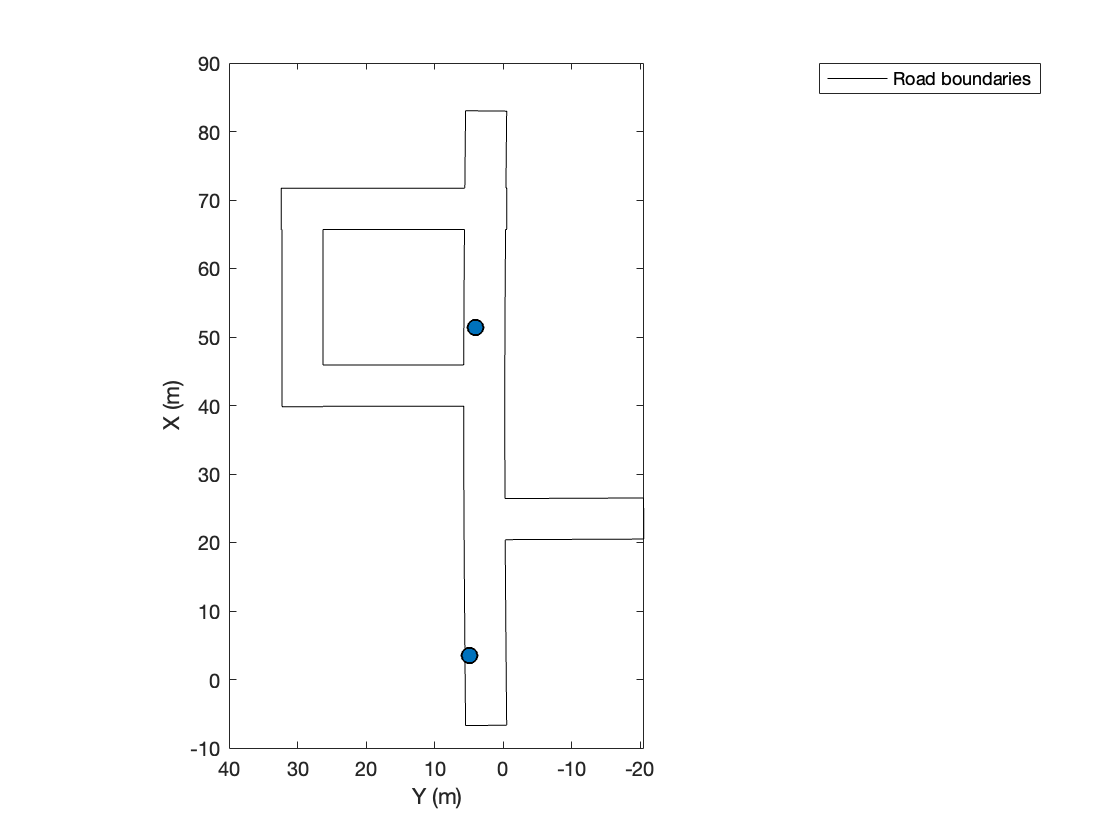

egoID=session.data.EgoCarId;
PlotterHelper(scenario,sensors,planner_wpts,ptLabels,EgoWayPts,egoID);

%%%% ref pre-loaded
ref=load('scenarios/scenario_4_turns.mat');
%refPose=ref.p.Position.data;
refPose=data.ActorSpecifications.Waypoints

refPose =    -5.0000    1.4000         0
    9.4000    1.4000         0
   19.9000    1.4000         0
   28.9000    1.4000         0
   32.7000    1.5000         0
   36.5000    1.4000         0
   39.4300    1.4000    0.0100
   40.5000    1.4000         0
   41.3800    1.5200    0.0100
   42.2000    1.7100    0.0100


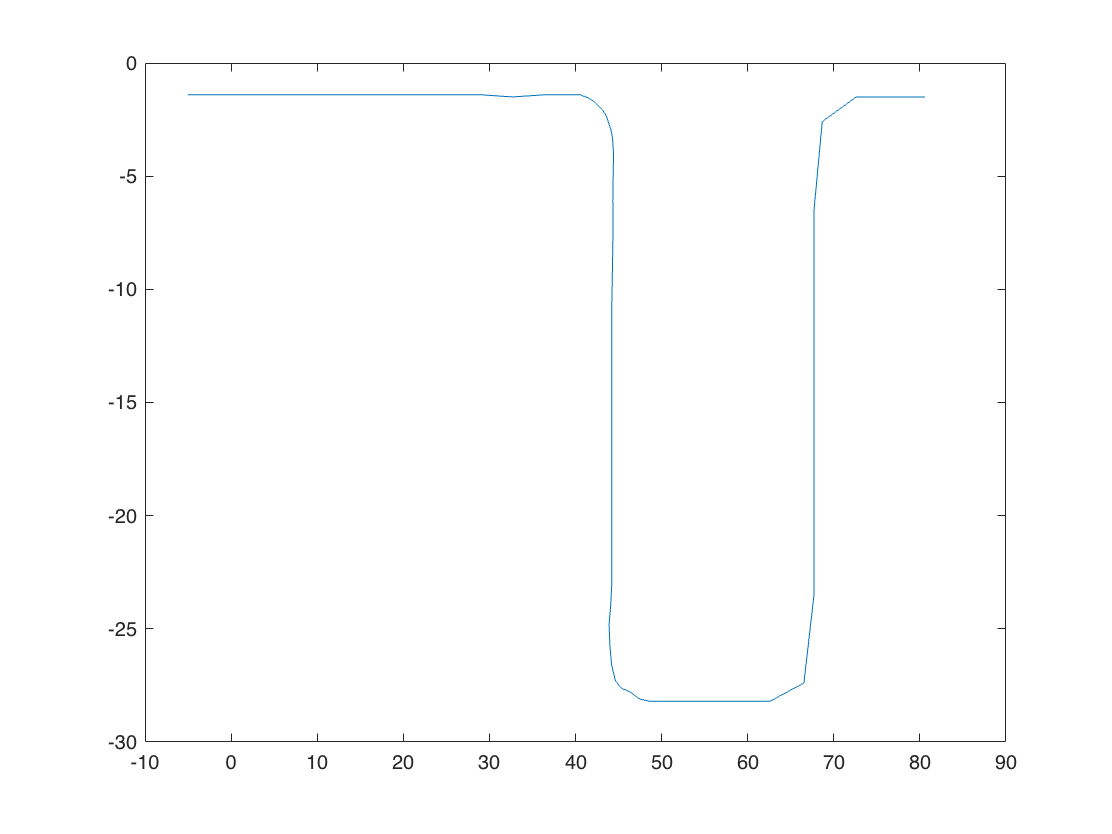

%ref=load('ego_pts_reference.mat');% Mcity
%refPose=ref.ego_pts.Position.data;% Mcity

%xRef = refPose(1,1,:);
%xRef = reshape(xRef,[],1);
%yRef = refPose(:,2,:)
%yRef = -reshape(yRef,[],1);
xRef=refPose(:,1);
yRef=-refPose(:,2);
X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction

X_f = xRef(length(xRef)); % final
Y_f = yRef(length(yRef)); 

distancematrix = squareform(pdist([xRef, yRef]));
distancesteps = zeros(length(refPose)-1,1);
for i = 2:length(refPose)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
totalDistance = sum(distancesteps); % Total distance travelled
distbp = cumsum([0; distancesteps]); % Distance for each waypoint
gradbp = linspace(0,totalDistance,1000); % Linearize distance

% linearize X and Y vectors based on distance
plot(xRef,yRef)

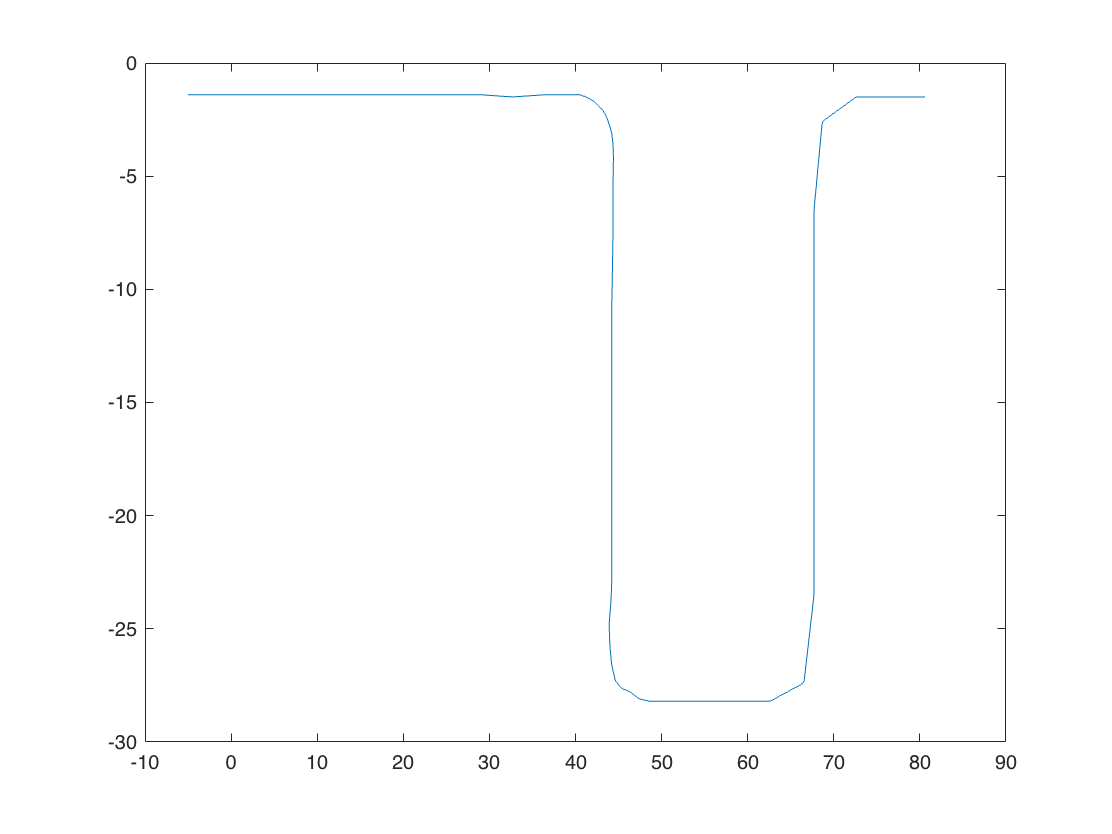

xRef2 = interp1(distbp,xRef,gradbp);
yRef2 = interp1(distbp,yRef,gradbp);
yRef2s = smooth(gradbp,yRef2); 
xRef2s = smooth(gradbp,xRef2); 
thetaRef = zeros(length(gradbp),1); 
for i = 2:length(gradbp)
    thetaRef(i,1) =atan2d((yRef2(i)-yRef2(i-1)),(xRef2(i)-xRef2(i-1)));
end
thetaRefs = smooth(gradbp,thetaRef); 
psi_o = thetaRefs(1)*(pi/180); % initial yaw angle
direction = ones(length(gradbp),1);
%direction = -sign(thetaRefs);
curvature = getCurvature(xRef2,yRef2);
plot(xRef2s,yRef2s)

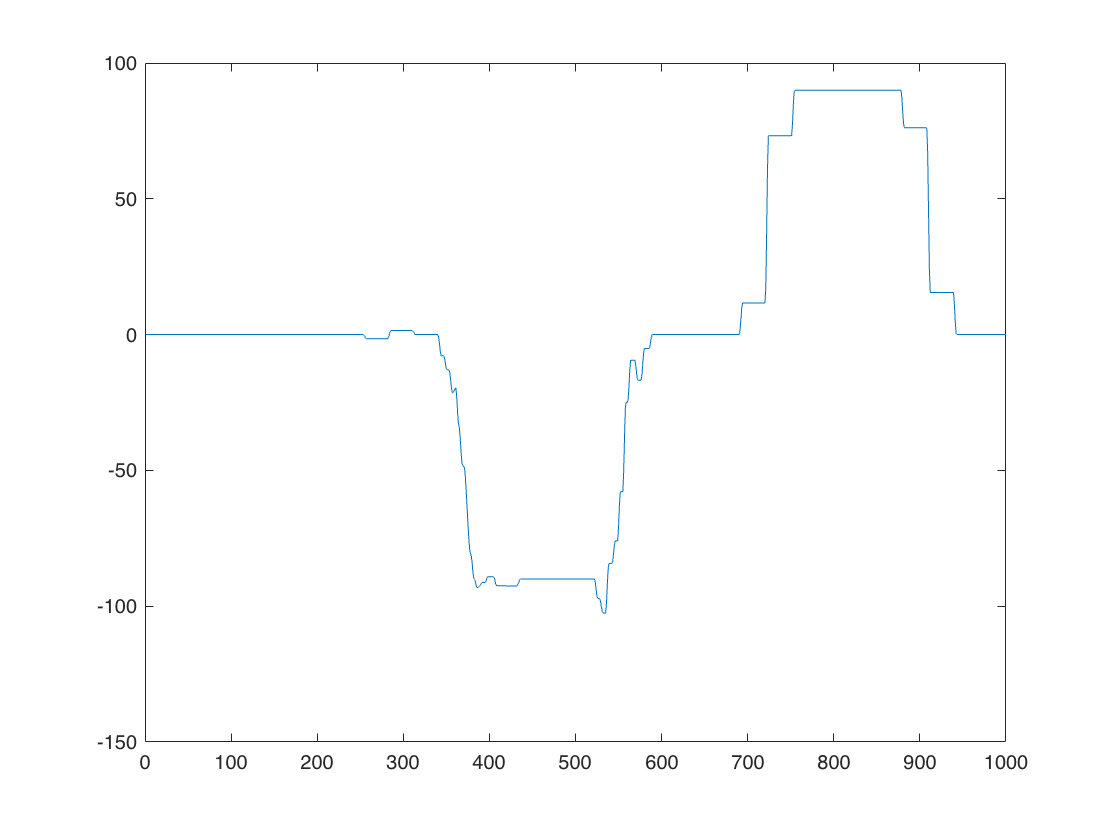

%plot(curvature)
figure(2);plot(thetaRefs)

point_intersection=[39.14 ,-0.; 71.7 , -0.5];

modelName='mode2';
model=append(modelName,'.slx');
open(model);
set_param(append(modelName,'/Scenario Reader'),'ScenarioFileName',scenarioLocation);
restart(scenario);
%sim('mode2.slx');

function curvature = getCurvature(xRef,yRef)
% Calculate gradient by the gradient of the X and Y vectors
DX = gradient(xRef);
D2X = gradient(DX);
DY = gradient(yRef);
D2Y = gradient(DY);
curvature = (DX.*D2Y - DY.*D2X) ./(DX.^2+DY.^2).^(3/2);
end